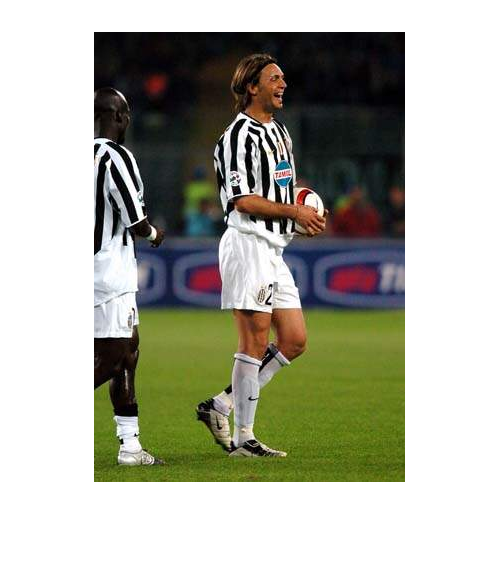

im = imread("juventus\02.jpg");
imshow(im);

f = size(im,1);
c = size(im,2);


## Crear histograma

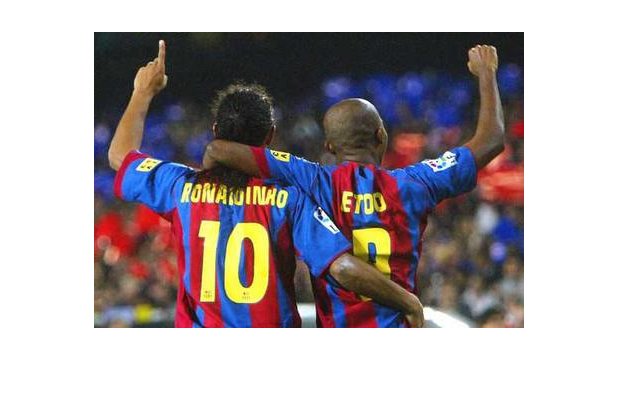

im = imread("barcelona\39.jpg");
imshow(im);

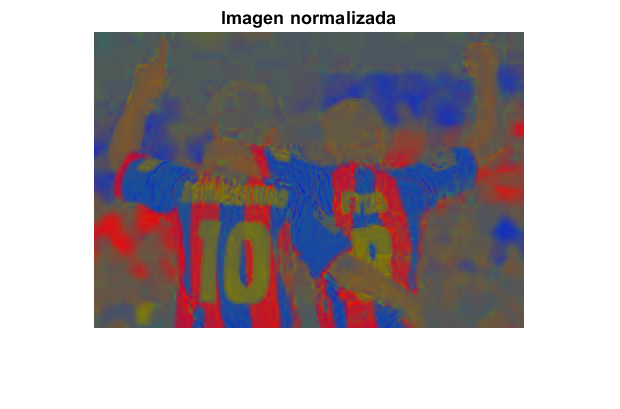

f = size(im,1);
c = size(im,2);

r=im(:,:,1);
g=im(:,:,2);
b=im(:,:,3);
I=double(r)+double(g)+double(b);
rn=double(r)./I;
gn=double(g)./I;
bn=double(b)./I;
rgbNorm=cat(3,rn,gn,bn);
figure,imshow(rgbNorm),title('Imagen normalizada');

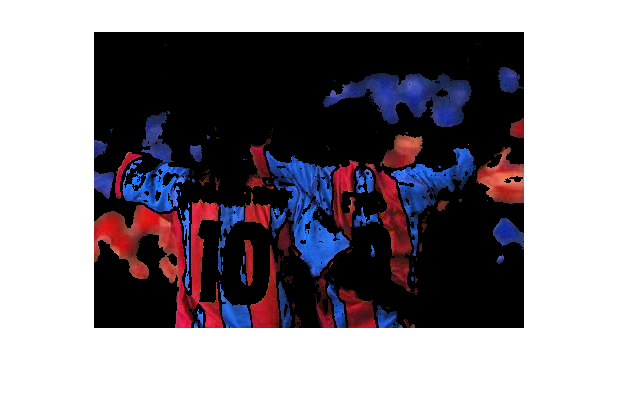

contR=0;
imFilter = uint8(zeros(f,c));
for i=1:f
    for j=1:c
        if rgbNorm(i,j,1) > 0.5
            if rgbNorm(i,j,2) < 0.3
                if rgbNorm(i,j,3) < 0.3
                    imFilter(i,j,1:3)=im(i,j,1:3);
                end
            end
        end
        if rgbNorm(i,j,3) > 0.5
            if rgbNorm(i,j,2) < 0.3
                if rgbNorm(i,j,1) < 0.3
                    imFilter(i,j,1:3)=im(i,j,1:3);
                end
            end
        end
    end
end
imshow(imFilter)

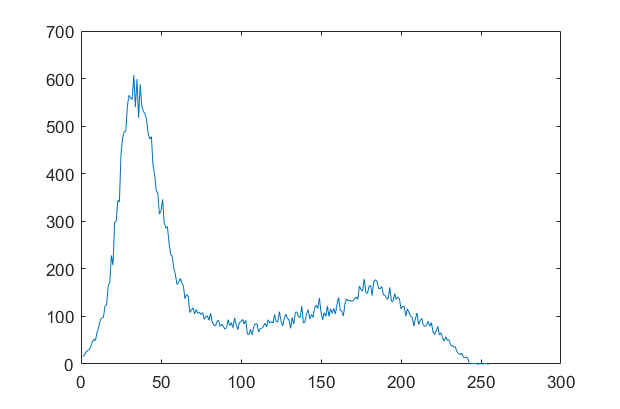

filtrado=imFilter;%%add(imFilter,imFilter2,imFilter3);
rh = imhist(imFilter(:,:,1));
subrh = rh(2:256);
plot(subrh);

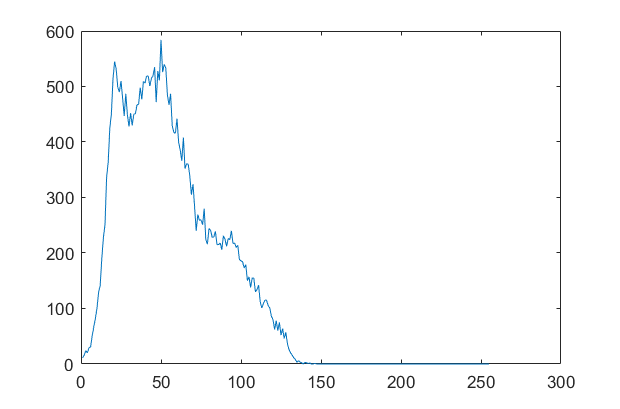

gh = imhist(imFilter(:,:,2));
subgh = gh(2:256);
plot(subgh);

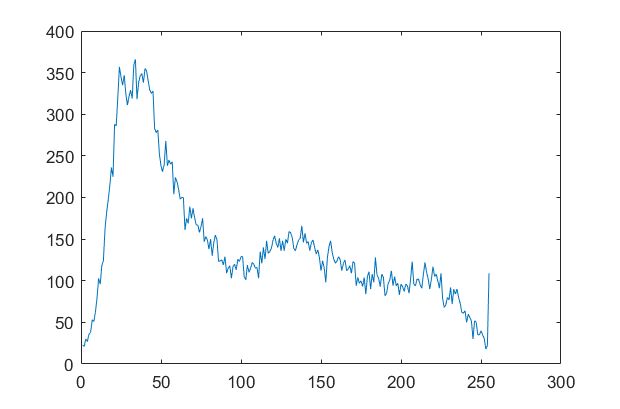

bh = imhist(imFilter(:,:,3));
subbh = bh(2:256);
plot(subbh);

imshow(filtrado);

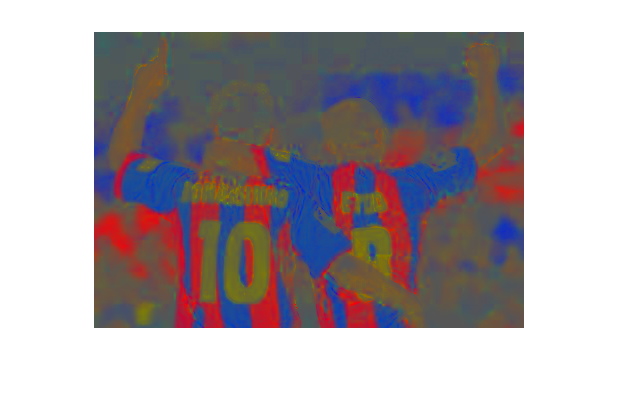

imshow(rgbNorm)

imshow(im);

contR/(f*c)

ans = 0

## Histograma colores separados

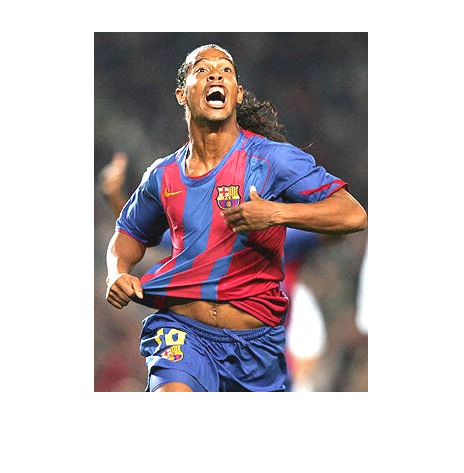




figure
imshow(im);

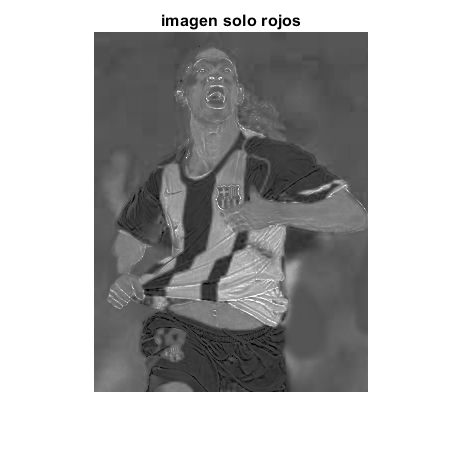

imshow(rn),title('imagen solo rojos');

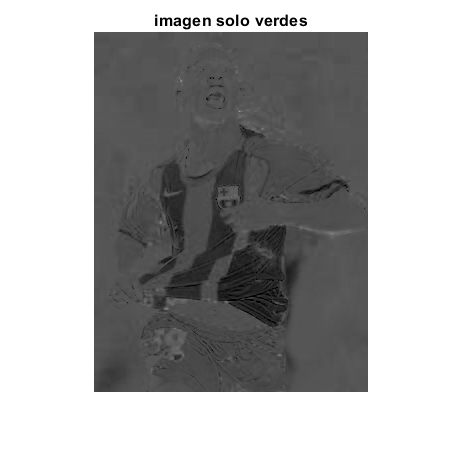

imshow(gn);title('imagen solo verdes');

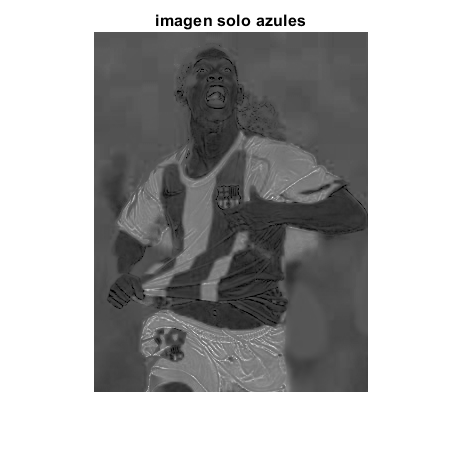

imshow(bn);title('imagen solo azules');

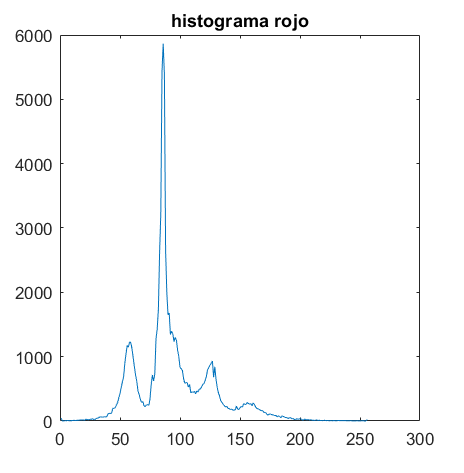

rh = imhist(rn);
gh = imhist(gn);
bh = imhist(bn);
plot(rh),title('histograma rojo');

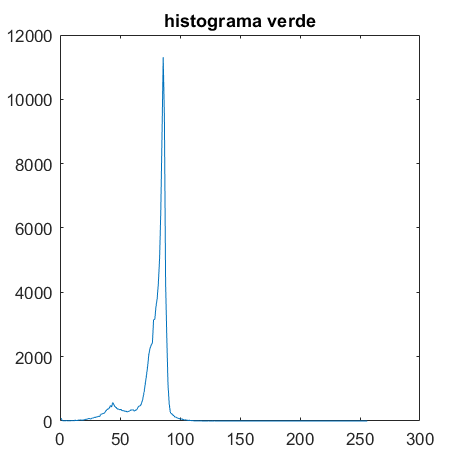

plot(gh),title('histograma verde');

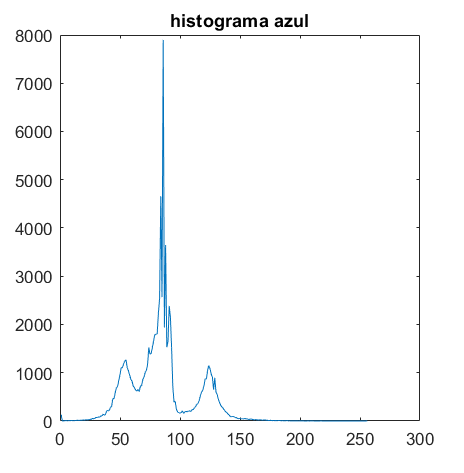

plot(bh),title('histograma azul');

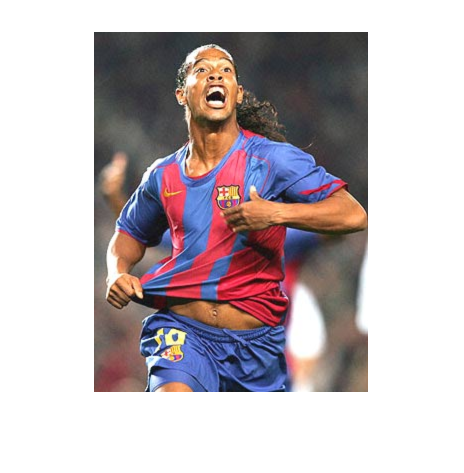



suav=imgaussfilt(im);
imshow(suav);

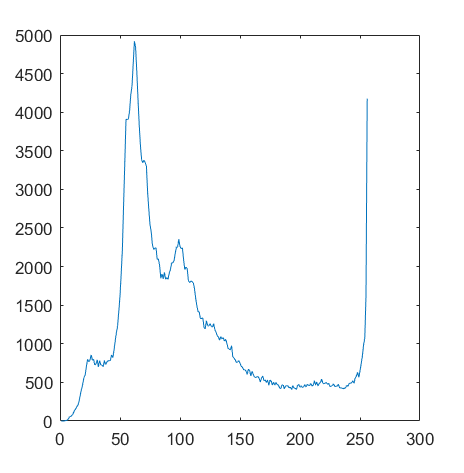

plot(imhist(suav));

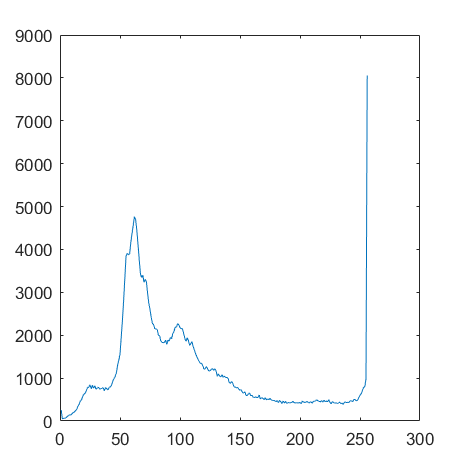

plot(imhist(im));